%wczytanie koniecznych parametrów i wyliczenie wzocnień oraz punktów równowagi 
clear all
close all
run("wyliczanie_jacobianow_oraz_p_row.mlx")

ans = 0.0100

mwag_cal = -18.2574

close all
initial_x = 0.013;
%initial_x = 0.011;
max_x = 0.0212;
expected_z = 0.01;
KW = -[polyval(p_z,expected_z) polyval(p_v,expected_z) polyval(p_i,expected_z)];
Kw = -[polyval(p_z,expected_z)*max_x polyval(p_v,expected_z) polyval(p_i,expected_z)*3];


GENERAL INFO

obsInfo = rlNumericSpec([3 1], LowerLimit=[-1 -1 -1]', UpperLimit=[ 1 1 1]');
actInfo = rlNumericSpec([1 1],"UpperLimit",1,"LowerLimit",0); 


obsInfo.Name = "observations";
obsInfo.Description = "position z, velocity v, current";
actInfo.Name = "control";

env = rlSimulinkEnv("MODEL_neural","MODEL_neural/controller",obsInfo,actInfo);
env.ResetFcn = @start;

Ts = 5e-3;
Tf = 0.5;
rng(0,"twister");

CRITIC



criticNet = [
    featureInputLayer(3,Name="observation")
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];


criticNet = dlnetwork(criticNet)

criticNet =   dlnetwork with properties:

         Layers: [8×1 nnet.cnn.layer.Layer]
    Connections: [7×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'observation'}
    OutputNames: {'QValueOutLyr'}
    Initialized: 1

  View summary with summary.


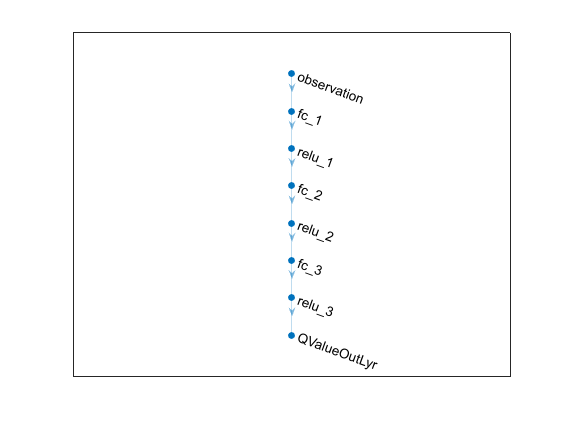

plot(criticNet)

summary(initialize(criticNet))


   Initialized: true

   Number of learnables: 2.8k

   Inputs:
      1   'observation'   3 features




% criticNet = initialize(criticNet);
% summary(criticNet)
critic = rlValueFunction(criticNet, ...
    obsInfo, ...
    UseDevice='gpu');


% commonPath = [
%     featureInputLayer(3,Name="observation")
%     ];
% 
% %commonPath(2).Weights=[4 6 0];
% %commonPath(2).Bias= 0
% 
% 
% meanPath = [
%     fullyConnectedLayer(1,Name="meanFC")
%     tanhLayer(Name="actionMean")
%     %fullyConnectedLayer(1,Name="actionMean",Weights=[1])
%     ];
% stdPath = [
%     fullyConnectedLayer(1,Name="stdFC", Weights = [0.1 0.1 0.1], Bias = [0.2])
%     sigmoidLayer(Name="actionStd")
%     %reluLayer(Name="stdFC")
%     ];


commonPath = [
    featureInputLayer(3,Name="observation")
    fullyConnectedLayer(64)
    reluLayer()
    fullyConnectedLayer(32)
    reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(16,Name="meanFC")
    reluLayer
    fullyConnectedLayer(1)
    % tanhLayer
    sigmoidLayer(Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(1,Name="stdFC", WeightsInitializer="zeros", Bias=0.1)
    sigmoidLayer(Name="actionStd")
    ];


actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"commonPath","meanFC/in");
actorNet = connectLayers(actorNet,"commonPath","stdFC/in");
summary(initialize(actorNet))


   Initialized: true

   Number of learnables: 2.9k

   Inputs:
      1   'observation'   3 features



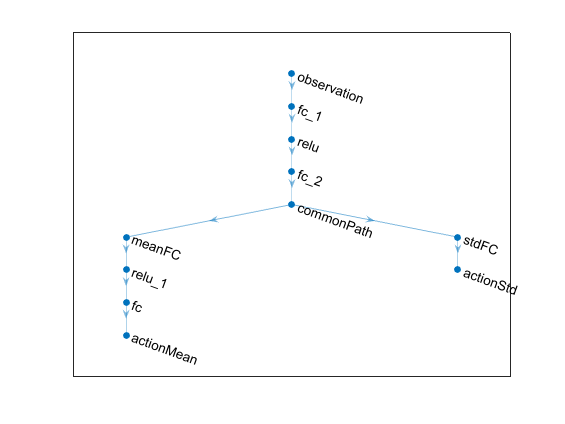

plot(actorNet)

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd", ...
    UseDevice='gpu');

AGENT


agentOpts = rlPPOAgentOptions( ...
    SampleTime             = Ts, ...
    ExperienceHorizon =     1500, ...
    DiscountFactor         = 0.95 ...
    );

%agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 5e-4;
agentOpts.ActorOptimizerOptions.GradientThreshold = 10;

%agentOpts.ActorOptimizerOptions.OptimizerParameters

%agentOpts.CriticOptimizerOptions(1).Algorithm = "adam";
agentOpts.CriticOptimizerOptions(1).LearnRate = 1e-3;
agentOpts.CriticOptimizerOptions(1).GradientThreshold = 10;



agent = rlPPOAgent(actor,critic,agentOpts);

% training options
trainOpts = rlTrainingOptions(...
    MaxEpisodes=14000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    StopTrainingCriteria= "EpisodeReward" , ...
    StopTrainingValue = -9.9, ...
    SimulationStorageType="none");

% StopTrainingCriteria= "none" , ...
evl = rlEvaluator(EvaluationFrequency=25, NumEpisodes=5);

    trainingOpts.UseParallel = true;
    trainingOpts.ParallelizationOptions.Mode = "sync";
    trainingOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;


doTraining = 1;

if doTraining
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
    save("PPO_agent64sigma_noBias.mat","agent")
end